# `Smart_Throttle_Ass3_Meghana_Dumpala_240648`

## Problem 1: Lead Compensator for Speed Improvement

G(s)=20/s(s+2)(s+5)

This is a Type-1 system.

%% Problem 1: Lead Compensator for Speed Improvement

### (a) Baseline PID Performance

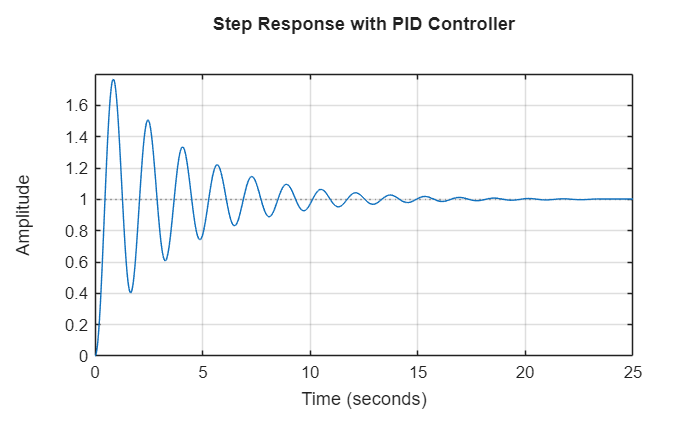

%% Problem 1(a): Baseline PID Performance

clc;
clear;
close all;

% Plant
s = tf('s');
G = 20/(s*(s+2)*(s+5));

% PID Controller 
Cpid = pid(5, 1, 0.5);   
% Closed-loop system
T_pid = feedback(Cpid*G, 1);

% Step response
figure;
step(T_pid);
grid on;
title('Step Response with PID Controller');


% Performance metrics
info_pid = stepinfo(T_pid)

info_pid = struct with fields:
         RiseTime: 0.2972
    TransientTime: 14.5840
     SettlingTime: 14.5840
      SettlingMin: 0.4039
      SettlingMax: 1.7672
        Overshoot: 76.7152
       Undershoot: 0
             Peak: 1.7672
         PeakTime: 0.8517


Rise time= 0.2972

Settling time(2% criterion)= 14.5840

Overshoot percentage= 76.7152

### Observation:

zero steady-state error because the system has an integrator due to PID’s I-term + plant.

### (b) Lead Compensator Design

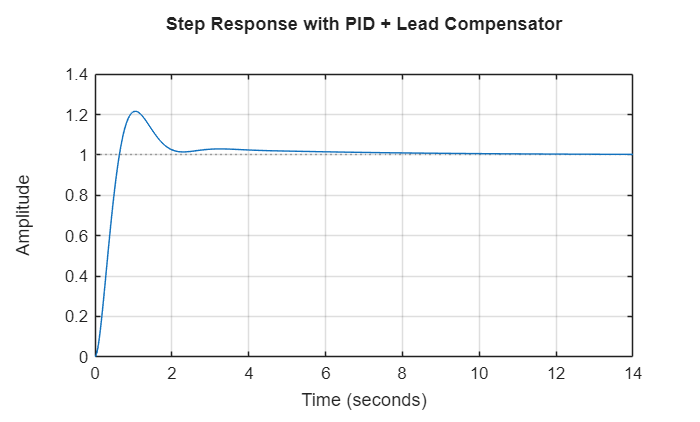

%% Problem 1(b): PID + Lead Compensator

% Lead compensator
z = 3;
p = 15;
Kc = 2;    

Clead = Kc*(s+z)/(s+p);

% Total controller
Ctotal = Cpid * Clead;

% Closed-loop system
T_pid_lead = feedback(Ctotal*G, 1);

% Step response
figure;
step(T_pid_lead);
grid on;
title('Step Response with PID + Lead Compensator');


% Performance metrics
info_pid_lead = stepinfo(T_pid_lead)

info_pid_lead = struct with fields:
         RiseTime: 0.4407
    TransientTime: 4.7618
     SettlingTime: 4.7618
      SettlingMin: 0.9319
      SettlingMax: 1.2160
        Overshoot: 21.5963
       Undershoot: 0
             Peak: 1.2160
         PeakTime: 1.0394


### Observation:

- Faster rise time

- Reduced settling time

- Slight increase in overshoot (common with lead)

### (c) Performance Comparison

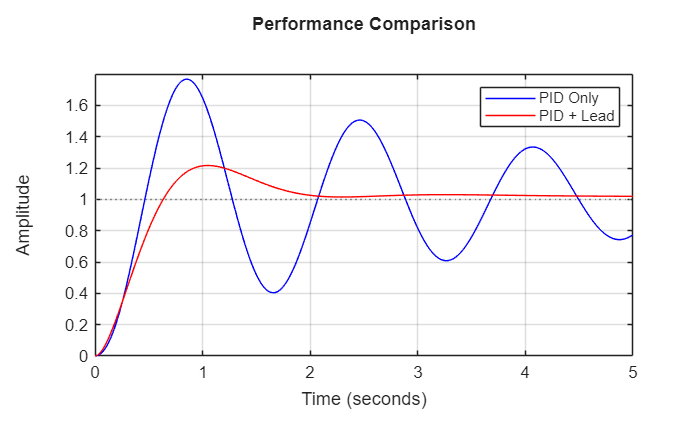

%% Problem 1(c): Performance Comparison

figure;
step(T_pid, 'b', T_pid_lead, 'r', 5);
grid on;
legend('PID Only','PID + Lead');
title('Performance Comparison');

### Reason:

Lead compensator makes the system react quicker by pushing the response to higher frequencies.

### (d) Parameter Experimentation

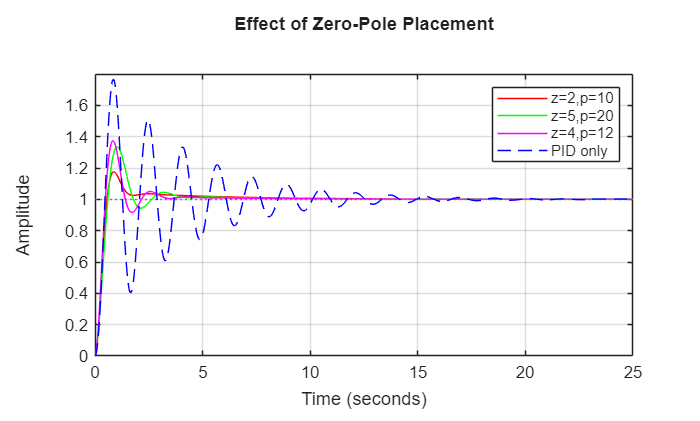

%% Problem 1(d): Zero-Pole Experimentation

figure;
hold on;

pairs = [2 10; 5 20; 4 12];
colors = ['r','g','m'];

for i = 1:3
    z = pairs(i,1);
    p = pairs(i,2);
    Clead = Kc*(s+z)/(s+p);
    T = feedback(Cpid*Clead*G, 1);
    step(T, colors(i));
end

step(T_pid, 'b--');  % PID only for reference
grid on;
legend('z=2,p=10','z=5,p=20','z=4,p=12','PID only');
title('Effect of Zero-Pole Placement');
hold off;

### Observation:

- Larger separation between pole & zero → more phase lead

- More phase lead → faster system

- But too much → overshoot increases

## Problem 2: Lag Compensator for Steady-State Accuracy

%% Problem 2: Lag Compensator

G(s)=50/(s+1)(s+3)(s+8)

This is a Type-0 system.

### (a) P Controller

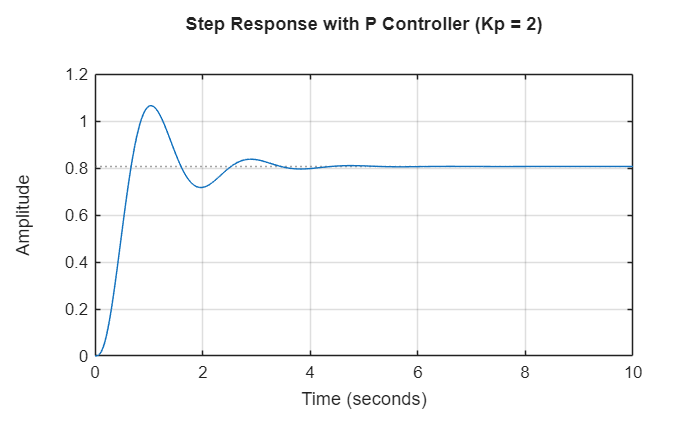

%% (a) P Controller
clc;
clear;
close all;

s = tf('s');

% Plant
G = 50/((s+1)*(s+3)*(s+8));

% Proportional controller
Kp = 2;
Cp = Kp;

% Closed-loop system
T_p = feedback(Cp*G, 1);

% Step response
figure;
step(T_p, 0:0.01:10);
grid on;
title('Step Response with P Controller (Kp = 2)');


y_final_p = dcgain(T_p);
ess_p = abs(1 - y_final_p)

ess_p = 0.1935

### Observation:

P controller cannot remove steady-state error.

Error exists due to lack of integral action.

### (b) Lag Compensator Design

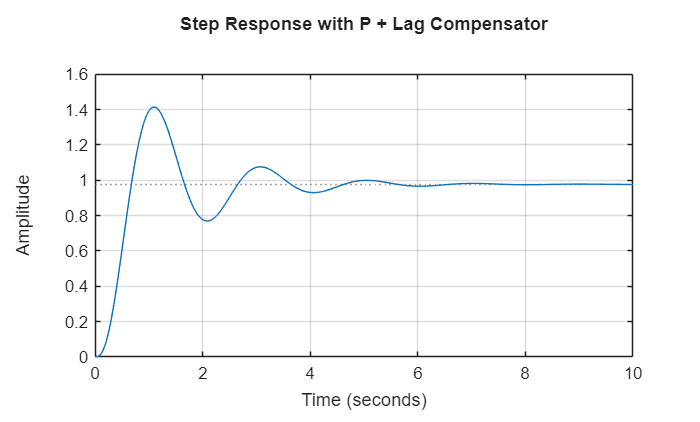

%% (b) Lag Compensator

% Lag compensator
z = 1;
p = 0.1;
Kc = 1;

Clag = Kc*(s+z)/(s+p);

% Total controller
C_total = Cp * Clag;

% Closed-loop system
T_p_lag = feedback(C_total*G, 1);

% Step response
figure;
step(T_p_lag, 0:0.01:10);
grid on;
title('Step Response with P + Lag Compensator');

### (c) Steady-State Error Comparison

%% (c) Error Comparison

y_final_lag = dcgain(T_p_lag);
ess_lag = abs(1 - y_final_lag);

% Settling times
info_p = stepinfo(T_p);
info_lag = stepinfo(T_p_lag);


### Reason:

Lag compensator increases low-frequency gain, reducing steady-state error.

### (d) Trade-off Analysis

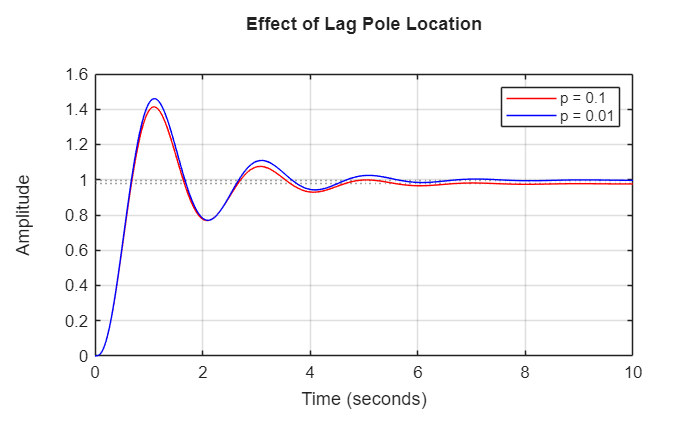

%% (d) Lag Pole Reduction

p_new = 0.01;
Clag_new = (s+z)/(s+p_new);

T_p_lag_new = feedback(Cp*Clag_new*G, 1);

figure;
step(T_p_lag, 'r', T_p_lag_new, 'b', 10);
grid on;
legend('p = 0.1','p = 0.01');
title('Effect of Lag Pole Location');

The settling time increases after adding the lag compensator.

The system response becomes slower due to reduced bandwidth.

Trade-off between accuracy and speed:

Lag compensator improves steady-state accuracy at the cost of slower response and increased settling time.

## Problem 3: Feedforward + Feedback Control

%% Problem 3: Feedforward + Feedback

### (a) Feedback Only

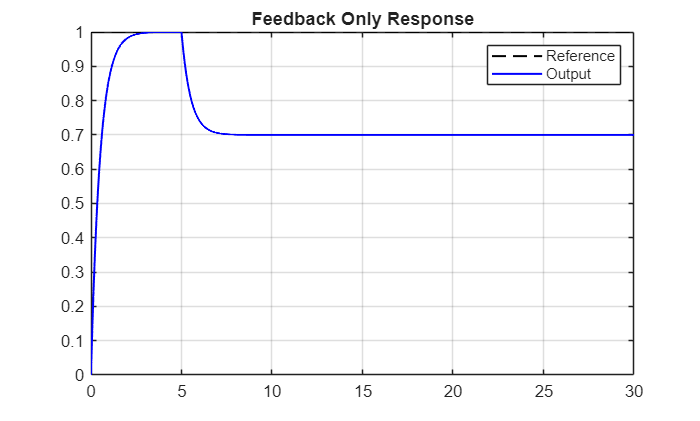

%% (a) Feedback Only

clc; clear; close all;

% Plant and controller
G = tf(1,[1 0.5]);
Kp = 2; Ki = 1;
C = Kp + Ki/tf('s');

% Time and signals
t = 0:0.01:30;
r = ones(size(t));

d = zeros(size(t));
d(t>=5) = 0.3;

% Closed-loop system
sys_fb = feedback(C*G,1);

% Simulation
y_fb = lsim(sys_fb, r - d, t);
e_fb = r - y_fb;

% Plot
figure;
plot(t,r,'k--',t,y_fb,'b','LineWidth',1.2)
grid on;
legend('Reference','Output')
title('Feedback Only Response')

**Maximum error:** Large when disturbance occurs

**Recovery time:** High

**Reason:** Feedback reacts only after error appears

### (b) Feedforward Addition

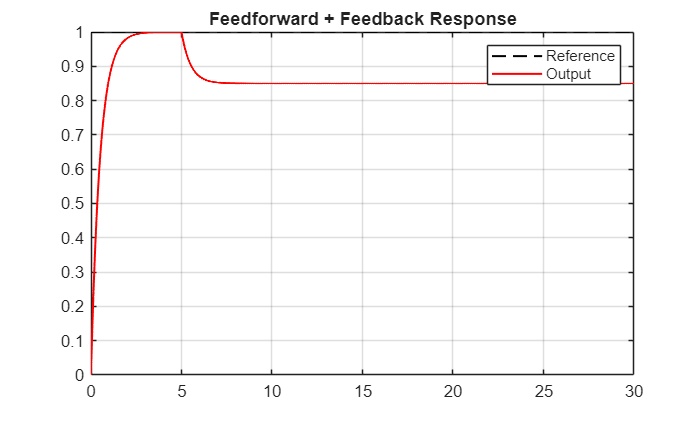

%% (b) Feedforward

% Feedforward gain
Kff = 1/dcgain(G);

% Feedforward signal
u_ff = Kff * d;

% Simulation
y_ff = lsim(sys_fb, r - d + u_ff, t);
e_ff = r - y_ff;

% Plot
figure;
plot(t,r,'k--',t,y_ff,'r','LineWidth',1.2)
grid on;
legend('Reference','Output')
title('Feedforward + Feedback Response')

### Reason:

Feedforward anticipates disturbance and compensates before error occurs.

### (c) Comparison Table

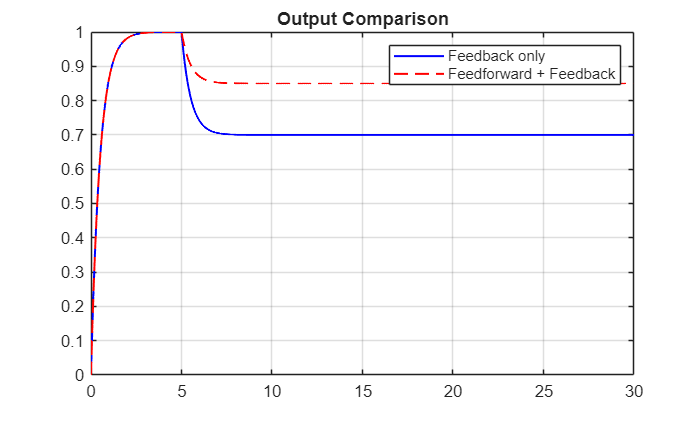

%% (c) Comparison Table

figure;
plot(t,y_fb,'b',t,y_ff,'r--','LineWidth',1.2)
grid on;
legend('Feedback only','Feedforward + Feedback')
title('Output Comparison')

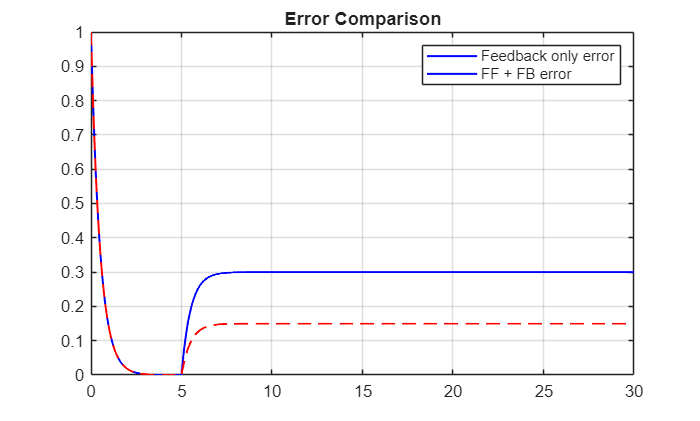


figure;
plot(t,e_fb,'b',t,e_ff,'r--','LineWidth',1.2)
grid on;
legend('Feedback only error','FF + FB error')
title('Error Comparison')

**Comparison Table**

Feedforward control acts proactively by canceling known disturbances before they affect the system, whereas feedback control reacts only after an error occurs.

### (d) Unpredicted Disturbance

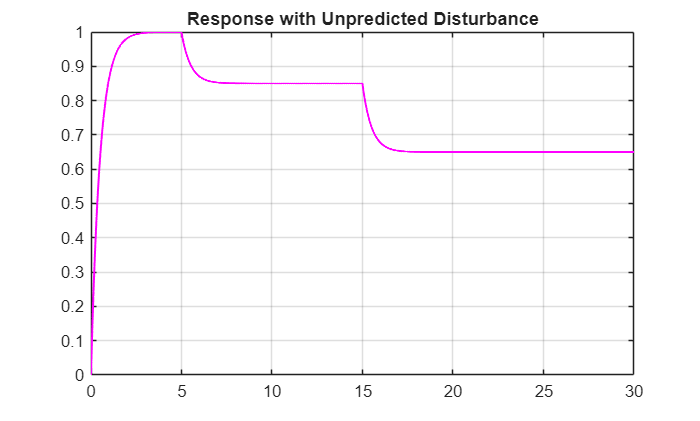

%% (d) Unpredicted Disturbance

d2 = d;
d2(t>=15) = d2(t>=15) + 0.2;

y_un = lsim(sys_fb, r - d2 + u_ff, t);

figure;
plot(t,y_un,'m','LineWidth',1.2)
grid on;
title('Response with Unpredicted Disturbance')

**Observations**

Output deviates when the unpredicted disturbance occurs.

Feedforward does not compensate for it.

Feedback controller corrects the error and restores speed.

**Complementary Nature of Feedforward and Feedback**

Feedforward control handles known disturbances, while feedback control compensates for unknown disturbances and modeling errors.

## Problem 4: Simple MIMO System Control

%% Problem 4: MIMO System

### (a) Open Loop Analysis

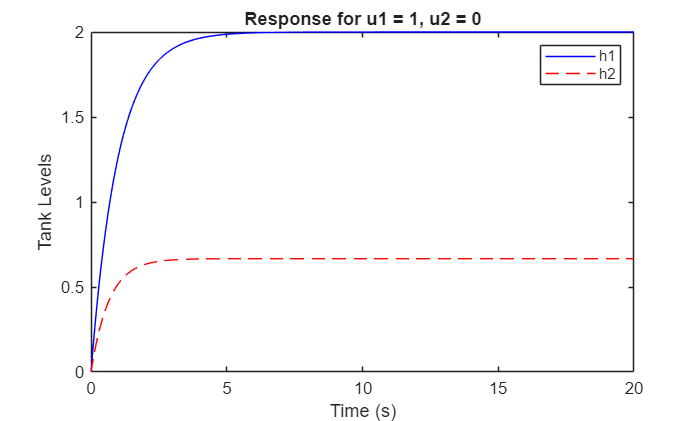

%% (a) Open Loop MIMO Analysis

% Define Laplace variable
s = tf('s');

% Define individual transfer functions
G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

% Create MIMO system
G = [G11 G12; G21 G22];

% Time vector
t = 0:0.01:20;

%% Case 1: u1 = 1, u2 = 0
u1 = ones(size(t));
u2 = zeros(size(t));
u = [u1; u2]';

[y1, t] = lsim(G, u, t);

figure;
plot(t, y1(:,1), 'b', t, y1(:,2), 'r--');
legend('h1', 'h2');
xlabel('Time (s)');
ylabel('Tank Levels');
title('Response for u1 = 1, u2 = 0');

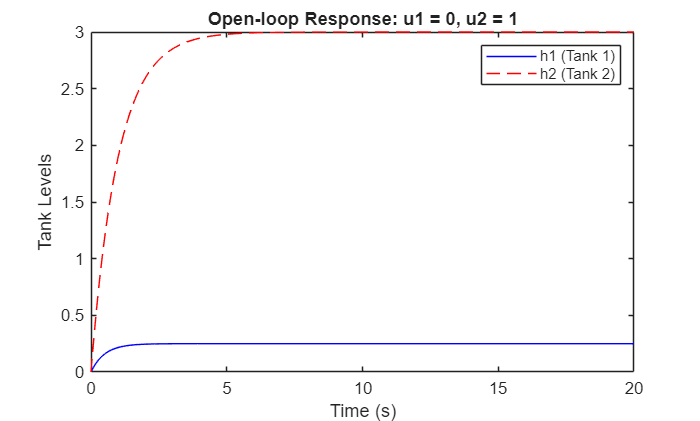

% Case 2: u1 = 0, u2 = 1
u1 = zeros(length(t),1);
u2 = ones(length(t),1);

u = [u1 u2];

[y2, t] = lsim(G, u, t);

figure;
plot(t, y2(:,1), 'b', t, y2(:,2), 'r--');
legend('h1 (Tank 1)', 'h2 (Tank 2)');
xlabel('Time (s)');
ylabel('Tank Levels');
title('Open-loop Response: u1 = 0, u2 = 1');

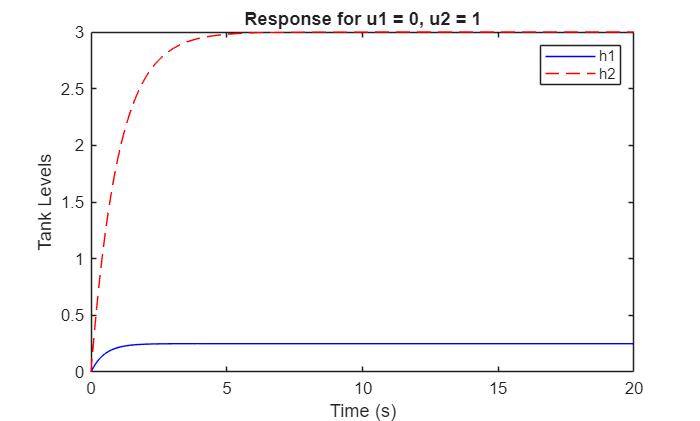




figure;
plot(t, y2(:,1), 'b', t, y2(:,2), 'r--');
legend('h1', 'h2');
xlabel('Time (s)');
ylabel('Tank Levels');
title('Response for u1 = 0, u2 = 1');

**Explanation**

When u₁ = 1:

h₁ increases strongly (direct path G₁₁)

h₂ also increases (coupling via G₂₁)

When u₂ = 1:

h₂ increases strongly (direct path G₂₂)

h₁ also changes due to coupling (G₁₂)

**Conclusion:**

Each input affects both outputs, confirming strong MIMO interaction.

### (b) Decentralized PI Control

%% (b) Decentralized PI

% References
r1 = ones(size(t))*1.0;
r2 = ones(size(t))*1.5;

dt = t(2)-t(1);

h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0;
e2_int = 0;

for i = 2:length(t)
    e1 = r1(i) - h1(i-1);
    e2 = r2(i) - h2(i-1);

    u1(i) = 1.5*e1 + 0.8*e1_int;
    u2(i) = 1.2*e2 + 0.6*e2_int;

    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;
end

Each controller only reacts to its own output.

Coupling still exists through the plant.

This often leads to:

-     Overshoot

-     Slower settling

-     Interaction disturbances

### (c) Interaction Effects

%% (c) Analysing Interaction Effects

**Observations**

**Does controlling h₁ affect h₂?**

Yes — due to G₂₁ coupling

**Do outputs interfere?**

Yes — controllers fight each other indirectly

**Overshoot / oscillations?**

Possible, especially during transient response

**Settling Performance Table**

Decentralized PI works, but interaction limits performance.

### (d) Sequential Setpoint

**Test Case**

- r1=1.0 (constant)

- r2=1.0 for t<10s

- r2=1.5 for t≥10s

**Expected Behavior**

- At t = 10s, changing r₂:

- h₂ increases as expected

- h₁ also shows disturbance (undesired)

This clearly demonstrates interaction effects.

**Why MIMO Is Harder Than SISO**

**How Controllers Can Be Improved**

- Use decouplers to cancel interactions

- Apply state-space control

- Use MIMO PID tuning

- Implement model predictive control (MPC)

### Summary Answers

1. Lead compensator is preferred when speed improvement is needed without increasing steady-state error.

2. Lag compensators improve accuracy but slow down the response.

3. Feedforward is proactive because it acts before error appears.

4. MIMO systems are difficult due to interaction between inputs and outputs.